% Constant
e = 1.6 * 10^-19;

% Pre-defined var
precut_start = 1;
precut_end = 8;
aftercut_start = 9;
aftercut_end = 38;
before_x_start = -1.3;
x_interval = 0.005;
before_x_end = 0.0;
after_x_start = -1.3;
after_x_end = 4.0;
label_x_pos = 3;
label_y_pos = -4.0*10^-4;
str = '436nm';

% Data saved here
lamda = 436;
U = [-1.2980 -1.2863 -1.2731 -1.2639 -1.2497 -1.2360 -1.2326 -1.2309 -1.2156 -1.2028 ...
   -1.1850 -1.1633 -1.1493 -1.1307 -1.1131 -1.1046 -1.0979 -1.0887 -1.0676 -1.0570 ...
    -1.0410 -1.0282 -1.0079 -0.9834 -0.9673 -0.9374 -0.9094 -0.6982 -0.5985 -0.4 -0.2 ...
    0 1 1.5 2 2.4980 2.9984 3.4989 3.9987 5.9990 7.9992 9.9991 11.9989 13.9994];
V = [-1.40 -1.37 -1.35 -1.34 -1.30 -1.23 -1.24 -1.21 -1.18 -1.14 -1.07 -0.99 -0.97 -0.9...
    -0.83 -0.77 -0.73 -0.69 -0.57 -0.50 -0.41 -0.33 -0.18 -0.01 0.14 0.43 0.72 3.93 6.3...
    11.32 20.40 27.54 50.72 56.18 59.66 63.25 66.30 67.35 68.13 71.00 73.23 74.00 ...
    74.18 74.30];

    size(U)

ans =      1    44


% Check if match and calculate A
if(size(U) == size(V))
    A = V .* 10^-3 .* 200 .* 10^-4;
else
    size(V)
    error("U V not match");
end

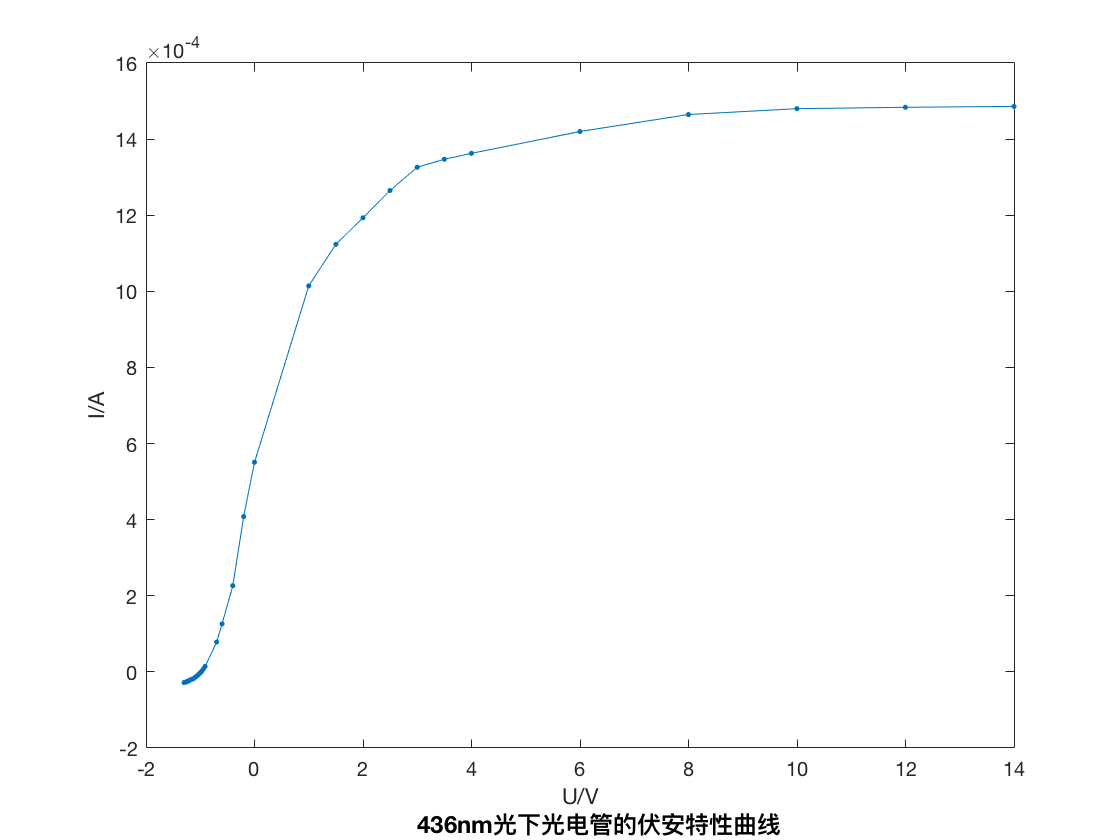

% Lets plot the first picture
figure;

plot(U, A, '.-');
axis on
hold on
xlabel('U/V')
ylabel('I/A')

% Create textbox
text(label_x_pos, label_y_pos, [str,'光下光电管的伏安特性曲线'], 'FontWeight','bold', 'FontSize',12)

% Make a slice
U_Before = U(precut_start:precut_end)';
A_Before = A(precut_start:precut_end)';

U_After = U(aftercut_start:aftercut_end)';
A_After = A(aftercut_start:aftercut_end)';

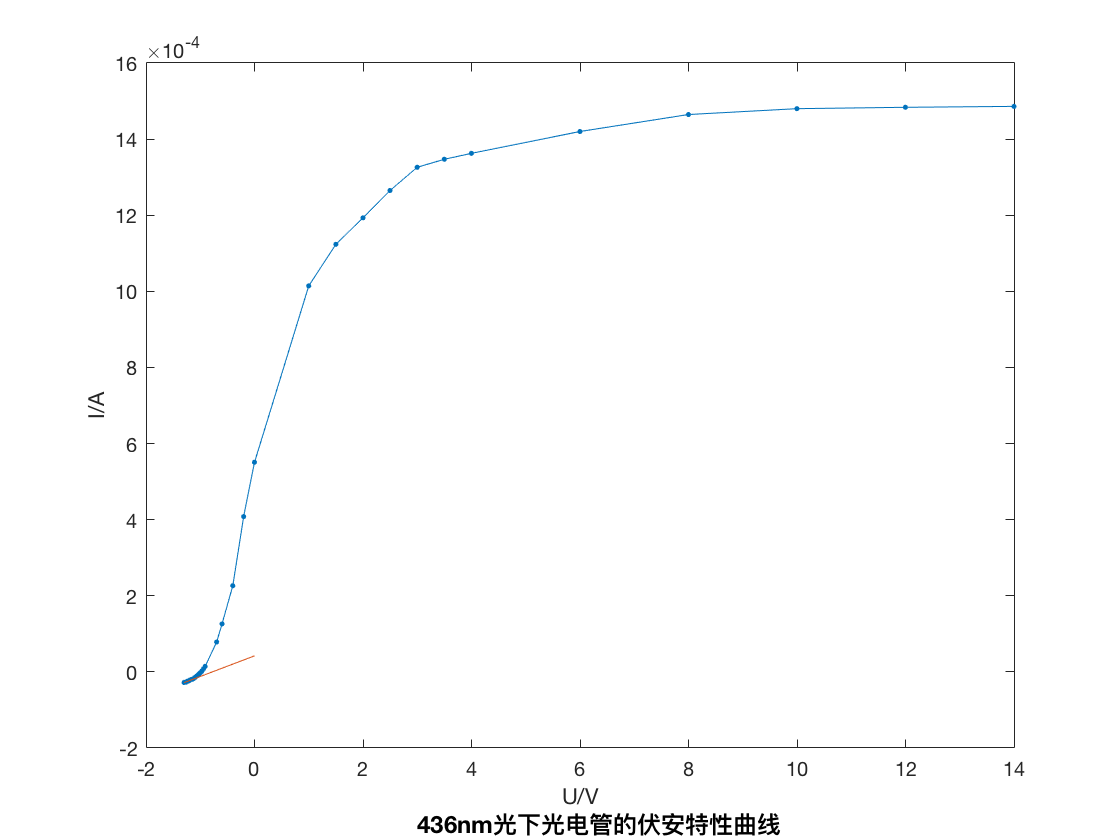

% Fit before
ftp = fittype('poly1');
fittedPic = fit(U_Before, A_Before, ftp);
fitx_before = before_x_start:x_interval:before_x_end;
fity_before = fittedPic(fitx_before);
plot(fitx_before, fity_before );

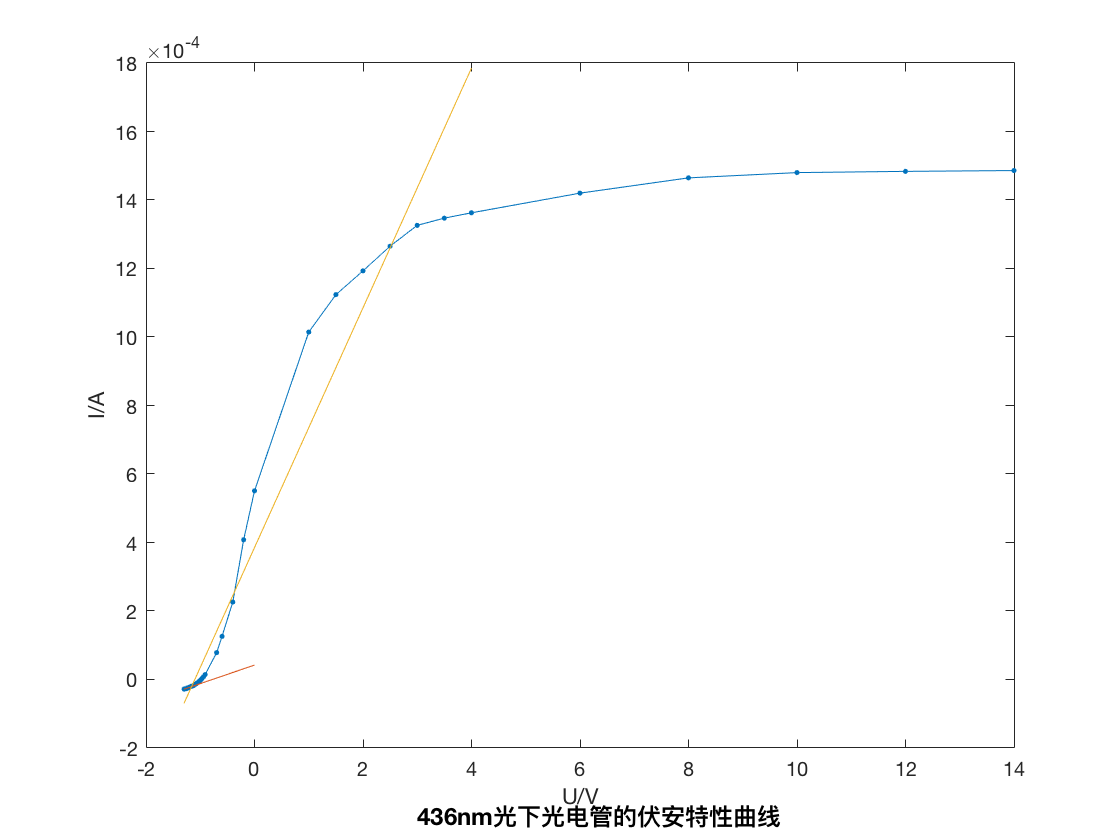

% Fit After
fittedPicA = fit(U_After, A_After, ftp);
fitx_After = after_x_start:x_interval:after_x_end;
fity_After = fittedPicA(fitx_After);
oic = plot(fitx_After, fity_After);

% Solve the points
syms x
eq = (fittedPic.p1 - fittedPicA.p1)*x + fittedPic.p2 - fittedPicA.p2 == 0;
px = solve(eq, x);
Ua = eval(px)

Ua =          -1.15987887734034
